
clear all;
close all;

colors = npg(100);
F=5/2;
sigmax = spinOp(F,'x');
sigmay = spinOp(F,'y');
sigmaz = spinOp(F,'z');

initial = zeros(2*F+1,1);
initial(1) = 1;

T = 7.8;   % 173周期,ms
ts = T*128;
timelist = [0:T/780:T];

%% 输入变量
tensor = 0.05;
Bz = 2*pi/T/5;   % omega量纲, 2pi*kHz, 对应ms

ROT = sigmax+sigmax^2;
ham = Bz*sigmaz+tensor*sigmaz^2;   % omega量纲

x = [1;2;3;4;5;6];
x = x./sqrt(x'*x);
temp = x;
%temp = ham_evolve(ROT,x,pi/2/8);
%temp = ham_evolve(ham,temp,78*5);

temp = ham_evolve(ROT,temp,pi/8);
temp = ham_evolve(ham,temp,78*5);
temp = ham_evolve(ROT,temp,pi);
temp = ham_evolve(ham,temp,78*5);
temp = ham_evolve(ROT,temp,pi/8);

temp = ham_evolve(ROT,temp,pi);

%temp = ham_evolve(ham,temp,78*5);
%temp = ham_evolve(ROT,temp,pi/2/8);

temp = abs(temp);


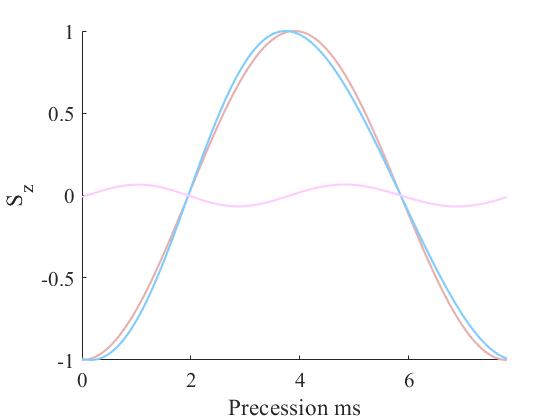


n = 5;

for k = 1:length(timelist)
    temp = ham_evolve(ROT,initial,pi/2);
    temp = ham_evolve(ham,temp,timelist(k)+ts);
    state1(:,k) = ham_evolve(ROT,temp,pi/2);
    state2(:,k) = ham_evolve(ROT,state1(:,k),pi);

    temp = ham_evolve(ROT,temp,pi/2/8);   % 171 pi/2
    temp = ham_evolve(ham,temp,78*n);    % 173 n倍周期

    temp = ham_evolve(ROT,temp,pi/8);   % 171 pi
    temp = ham_evolve(ham,temp,78*n);   % 173 n倍周期
    %temp = ham_evolve(ROT,temp,pi);
    %temp = ham_evolve(ham,temp,78*n);

    %temp = ham_evolve(ROT,temp,pi);

    %temp = ham_evolve(ROT,temp,pi/8);

    %temp = ham_evolve(ham,temp,78*n);
    %temp = ham_evolve(ROT,temp,pi/2/8);
    precess_state1(:,k) = ham_evolve(ROT,temp,pi/2-0.01*pi);
    %precess_state1(:,k) = ham_evolve(ROT,temp,pi/2-pi*(1/8+1/16));
    precess_state2(:,k) = ham_evolve(ROT,precess_state1(:,k),pi);
end
pop_state1 = abs(precess_state1).^2;
pop_state2 = abs(precess_state2).^2;


state1 = abs(state1).^2;
state2 = abs(state2).^2;

sz1(:) = (state1(1,:)-state2(1,:))./(state1(1,:)+state2(1,:));
sz2(:) = (pop_state1(1,:)-pop_state2(1,:))./(pop_state1(1,:)+pop_state2(1,:));
dsz = sz1-sz2;

f1 = figure; hold on;

plot(timelist,sz1,'-','LineWidth',1.6,'Color',[0.9 0.69 0.69]);
plot(timelist,sz2,'-','LineWidth',1.6,'Color',[0.5 0.8 1]);
plot(timelist,dsz,'-','LineWidth',1.6,'Color',[1 0.8 1]);
ylim([-1 1]);
xlim([min(timelist) max(timelist)]);
xlabel('Precession ms');
ylabel('S_z');

set(gca,'FontName','times new roman','FontSize',16);


set(f1,'Visible','on');

function final = ham_evolve(ham,initial,time)
try
    final = expm(-1i*ham.*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end

